# Interactive Figures and Images in MATLAB

### GUI With Interactive Response-Plot Updates

`uicontrol`** : create user interface control**

Style of `UIControl` object:

- `pushbutton`

- `togglebutton`

- `checkbox`

- `radiobutton`

- `edit`

- `text`

- `slider`

- `listbox`

- `popupmenu`

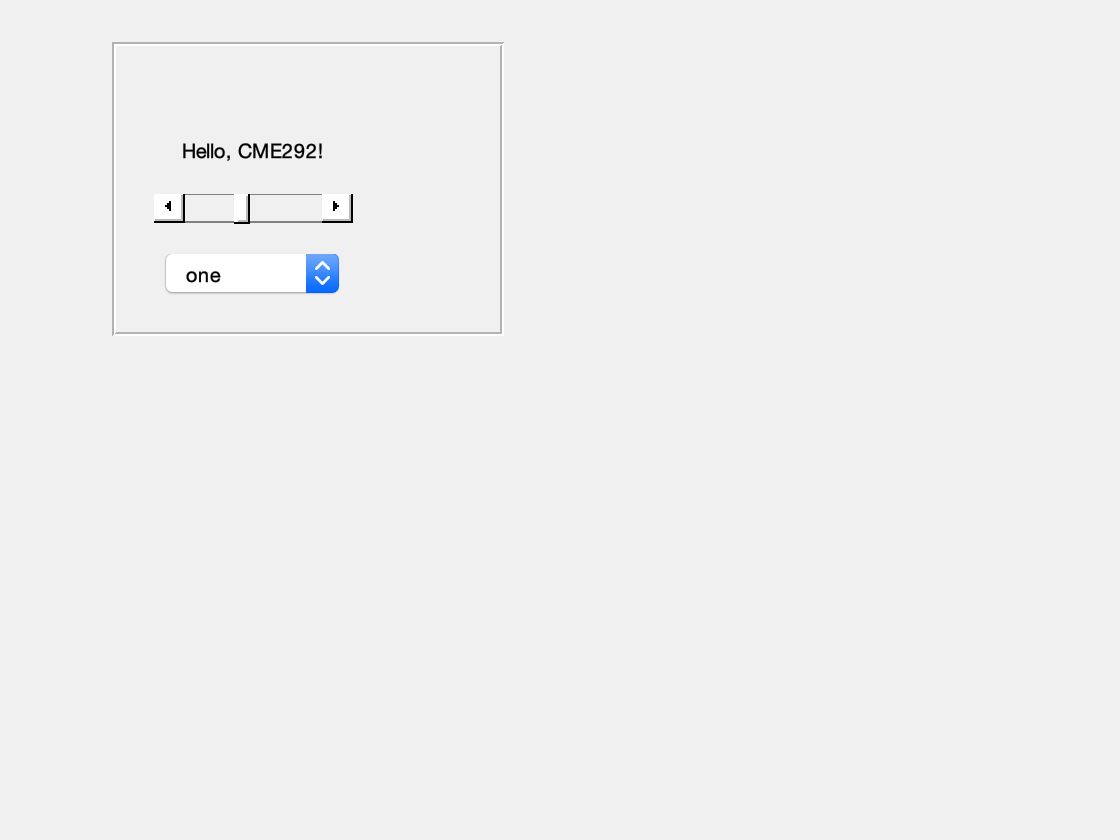

f = figure;
% create a figure and a panel positioned within it
p = uipanel(f,'Position',[0.1 0.6 0.35 0.35]);
% create a radio button within the panel
c1 = uicontrol(p,'Style','popupmenu',...
    'Position',[20 20 100 20],... % [left bottom width height]
    'String',{'one','two','three'});
% create a slider within the panel
c2 = uicontrol(p,'Style','slider',...
    'Position',[20 50 100 20], 'Value',0.4);
% create a text
c3 = uicontrol(p,'Style','text',...
    'Position',[20 80 100 20], 'String', "Hello, CME292!");

#### Helpful commands

`uifigure` creates a figure for building a user interface and returns the `Figure` object.

`uigridlayout` creates a grid layout manager for an app. It positions UI components along the rows and columns of an invisible grid that spans the entire figure or a container within the figure. 

`uipanel` creates a panel in the current figure and returns the `Panel` object. 

`uibutton` creates a push button in a new figure and returns the `Button` object.

`uislider` creates a slider in a new figure window and returns the `Slider` object.

... ...

**Demo**: `ex1.m`

#### Share Data Among Callbacks

**Graphics callback functions** must accept at least two input arguments:

- The handle of the object whose callback is executing. Use this handle within your callback function to refer to the callback object.

- The event data structure, which can be empty for some callbacks or contain specific information that is described in the property description for that object.

**UserData** is a property that all graphics objects in MATLAB possess, and can be used to store any single, user-defined array with a particular object.

**Demo: **`ex2.m`

**More Demo: **`ex3.m`

close all; clear; clc

### Identify Coordinates Using Cursor

`[x,y] = ginput(n)` 

allows us to identify the coordinates of `n` points within Cartesian, polar, or geographic axes. To choose a point, move the cursor to the desired location and press either a mouse button or a key on the keyboard. Press the **Return** key to stop before all `n` points are selected. The coordinates of your selected points are returned in `x,y`.

**Demo **

Get the latitude and longitude coordinates of five points by clicking the mouse. Plot them one by one and connect the points in order.

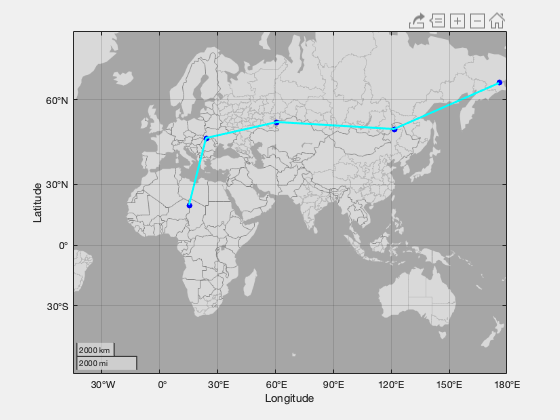

geoaxes
% geolimits('manual')
geolimits([-30 60],[-45 180])
n_pt = 5;
latlons = [];
for idx=1:n_pt
    [lat,lon] = ginput(1);
    latlons = [latlons;[lat,lon]];
    hold on
    geoscatter(lat,lon,'filled','b')
    if idx>1
        geoplot(latlons((idx-1):idx,1),latlons((idx-1):idx,2),...
            'c-','LineWidth',2)
    end
end

### Create ROI (Region of Interest) in Images

A **region of interest (ROI)** is a portion of an image that you want to filter or operate on in some way. We can represent an ROI as a binary mask image. In the mask image, pixels that belong to the ROI are set to `1` and pixels outside the ROI are set to `0`. [Image Processing Toolbox]

**Example 1: mask out region by selection.**

Create an `Ellipse `ROI. Specify properties to customize the appearance of the ellipse. Here, the face color is yellow and border of the ROI has a red stripe. 

roi = images.roi.Ellipse('Color','c','StripeColor','r');

Load image.

I = imread('cat.jpg');
imshow(I)

Draw the ROI on the image by clicking and draging the cursor over the image to create the elliptical shape. 

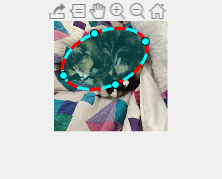

draw(roi)

roi

roi =   Ellipse with properties:

           Center: [102 82.5000]
         SemiAxes: [88.7694 54.8625]
    RotationAngle: 22.5206
      AspectRatio: 1.6180
            Label: ''
            Color: [0 1 1]
           Parent: [1×1 Axes]
          Visible: 'on'
         Selected: 0

  Show all properties


Create a binary mask from the ROI.

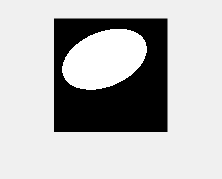

mask = createMask(roi);
imshow(mask)

Mask out area of ROI in image

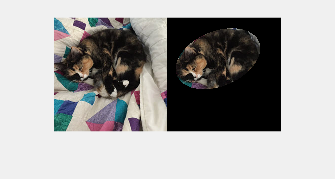

I2 = bsxfun(@times, I, cast(mask, 'like', I));
imshowpair(I,I2,"montage")

**Example 2: Freehand ROI**

imshow(I)

Draw a freehand ROI.

roi = drawfreehand;

Fill in the face of the freehand ROI. 

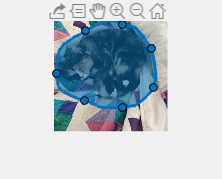

roi.FaceAlpha = 0.5;
roi.FaceSelectable = false;

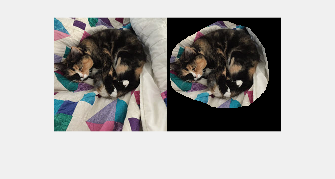

I2 = bsxfun(@times, I, cast(createMask(roi), 'like', I));
imshowpair(I,I2,"montage")